N=10;%Number of disjoint links to compute
topology='SpineLeaf';
k=8;
source='L1';
dest='L3';

G=graphTopology(false,false,topology,k,10);

paths=edgeDisjointNaiveDijkstra(G,source,dest,N,false);

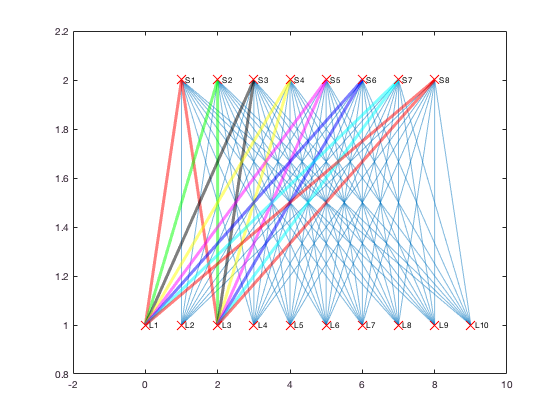

count = 1


%See the plot

p=plotGraphtopology(G);
list_color={'c','r','g','k','y','m','b'};
count=1;
for j=1:N
    count=count+1;
    if(count>7)
        count=1
    end
    highlight(p,paths{j},'EdgeColor',list_color{count},'LineWidth',3);
end